clear;
close all;
clc;
opts = bodeoptions('cstprefs');
opts.FreqUnits = 'Hz';

s = tf('s');
fpwm = 3800;


### 400V scenario trafo un Leitdrive connesso ad una linea a 250kVA

Pnom = 250e3; % potenza nominale apparente trafo di media: 20kV/400V 250 kVA
Unom = 400;
fnom = 50;
Inom = Pnom/sqrt(3)/Unom;
Ucc = 0.06; % tensione di corto circuito, dato di targa
L2 = Ucc * Unom/sqrt(3)/Inom/(2*pi*fnom) % calcolo della induttanza dispersa trafo

L2 = 1.2223e-04

RL2 = 0.02 * Pnom/3/Inom^2

RL2 = 0.0128

### dato filtro attuale 400V

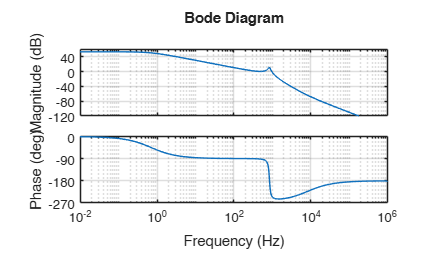

L1 = 330e-6;
RL1 = 2e-3;
RC = 50e-3;
C = 400e-6;

ZL1 = s*L1 + RL1;
ZRC = RC + 1/s/C;
ZL2 = s*L2;

Zp2 = minreal(ZL2 * ZRC / (ZL2 + ZRC));

H_ig_us = minreal(Zp2/((Zp2 + ZL1) * ZL2));
figure; bode(H_ig_us, opts); grid on


fres = 1/(2*pi*sqrt(C*L2)) % frequenza di risonanza tra il banco di condensatori del filtro LC e la leakage della linea

fres = 719.7795

f1 = fres

f1 = 719.7795

f2 = fres*1.2;
[Ares, fres] = getPeakGain(H_ig_us, 0.001, [f1, f2])

Ares = 3.1299

fres = 719.7795


% A_res = bode(H_ig_us,2*pi*fres)
% A_pwm = bode(H_ig_us,2*pi*fpwm)
A_res_dB = 20*log10(Ares)

A_res_dB = 9.9107

% A_pwm_dB = 20*log10(A_pwm)

### dato filtro 400V scenario 1

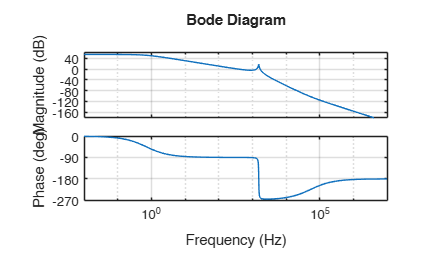

L1 = 330e-6;
RL1 = 2e-3;
RC = 25e-3;
C = 120e-6;

ZL1 = s*L1 + RL1;
ZRC = RC + 1/s/C;
ZL2 = s*L2;

Zp2 = minreal(ZL2 * ZRC / (ZL2 + ZRC));

H_ig_us = minreal(Zp2/((Zp2 + ZL1) * ZL2));
figure; bode(H_ig_us, opts); grid on


fres = 1/(2*pi*sqrt(C*L2)) % frequenza di risonanza tra il banco di condensatori del filtro LC e la leakage della linea

fres = 1.3141e+03

f1 = fres

f1 = 1.3141e+03

f2 = fres*1.2;
[Ares, fres] = getPeakGain(H_ig_us, 0.001, [f1, f2])

Ares = 1.7144

fres = 1.3141e+03


% A_res = bode(H_ig_us,2*pi*fres)
% A_pwm = bode(H_ig_us,2*pi*fpwm)
A_res_dB = 20*log10(Ares)

A_res_dB = 4.6820

% A_pwm_dB = 20*log10(A_pwm)